# **Script**

This script was utilized for report the results of the journal article: 

*Visualization of blood vessels in in-vitro raw speckle images using an energy-based decomposition criteria of the detail DWT coefficients *

F. Lopez-Tiro, H. Peregrina-Barreto, J. Rangel-Magdaleno and J. C. Ramirez-San-Juan,

clc; clear; close all;

Load raw speckle image from .mat file

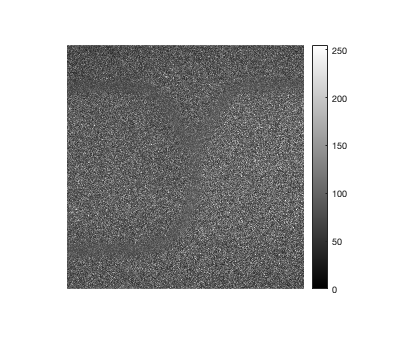

load('data.mat')
imshow(im_raw(:,:,1)); colormap gray; colorbar;

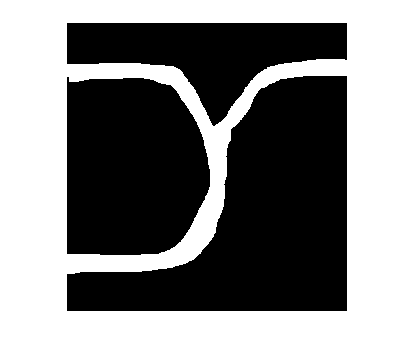

imshow(im_gt); colormap bone;

Parameters: size of the isometric window, wavelet function used and level of decomposition

type_window = 7;
type_wavelet = 'db5';
type_maxlevel = 5;

Computing spatial contrast and normalization values beetwen [0,1]

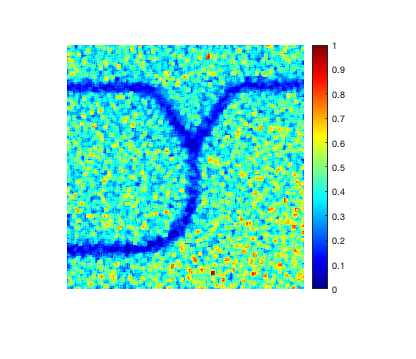

im_skavg = f_skavg(im_raw,type_window);
im_skavg = mat2gray(im_skavg);
imshow(im_skavg); colormap jet; colorbar

Wavelet approach 

for type_level = 1:1:type_maxlevel
    
    [im_synth, aux_energy] = f_denoising(im_skavg,type_wavelet,type_level);
    im_thresholded = f_thresholding(im_synth,im_skavg);
    im_segmented = f_segmenting(im_thresholded);
    cel_synthesized{type_level} = im_synth;
    cel_segmented{type_level} = im_segmented;
    
    if type_level == 1
        energy_level = aux_energy;
    else
        energy_level = vertcat(energy_level, aux_energy);
    end
    
end


Energy criterion

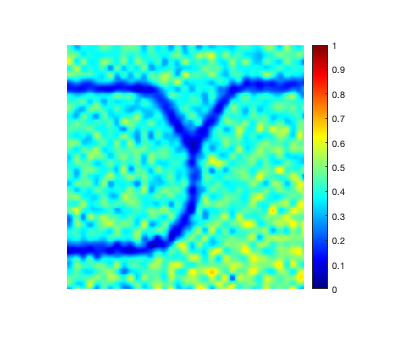

index_energy = f_ratio(energy_level);
index_energy = abs(index_energy);
im_denoised = cel_synthesized{index_energy};
imshow(im_denoised); colormap jet; colorbar

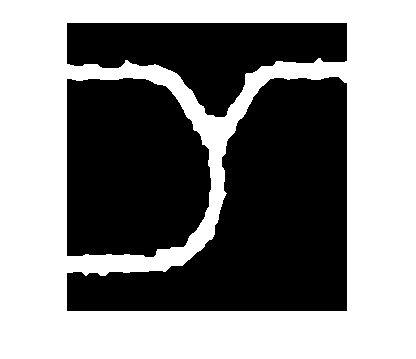

im_segmented = cel_segmented{index_energy};
imshow(im_segmented); colormap bone;

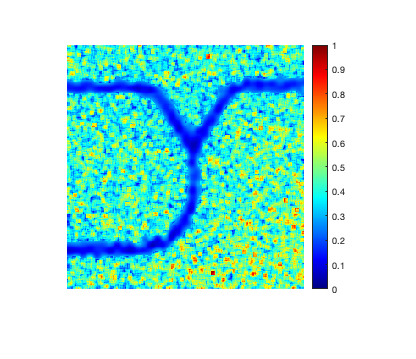

[im_improved, value_cnr] = f_improving(im_skavg,im_segmented,im_denoised);
value_ji = jaccard(im_segmented,im_gt);
imshow(im_improved); colormap jet; colorbar

function im_skavg = f_skavg(im_raw,type_window)

[rows_raw,cols_raw,frames_raw] = size(im_raw);
im_skavg_frames = zeros(rows_raw,cols_raw,frames_raw);

for type_slide = 1:1:frames_raw
    im_input = im_raw(:,:,type_slide);
    d = (type_window-1)/2;
    mat_header = im_input(1:d,:);
    mat_footer = im_input(end+1-d:end,:);
    mat_inside = [mat_header;im_input;mat_footer];
    mat_left = mat_inside(:,1:d);
    mat_right = mat_inside(:,end-d+1:end);
    im_aux = [mat_left, mat_inside, mat_right];
    [rows_contrast,cols_contrast] = size(im_aux);
    im_skavg_aux = zeros(rows_contrast,cols_contrast);
    
    for i = 1+d:1:rows_contrast-d
        for j = 1+d:1:cols_contrast-d
            value_window = im_aux(i-d:i+d,j-d:j+d);
            value_mean = mean2(value_window);
            value_std = std2(value_window);
            value_contrast = value_std/value_mean;
            im_skavg_aux(i,j) = value_contrast;
        end
    end
    im_skavg_frames(:,:,type_slide) = im_skavg_aux(d+1:end-d,d+1:end-d);
end

im_skavg = mean(im_skavg_frames,3);
im_skavg = mat2gray(im_skavg);

end


function [im_synth,array_energy] = f_denoising(im_skavg,type_velet,type_level)

[C,S] = wavedec2(im_skavg,type_level,type_velet);
[H,V,D] = detcoef2('all',C,S,type_level);
A = appcoef2(C,S,type_velet);
array_energy = [f_energy(A), f_energy(H),f_energy(V),f_energy(D)]; % Modified Energy Vector

switch type_level
    case 1
        im_synth = idwt2(A,[],[],[],type_velet);
    case 2
        l1 = idwt2(A,[],[],[],type_velet);
        im_synth = idwt2(l1,[],[],[],type_velet);
    case 3
        l1 = idwt2(A,[],[],[],type_velet);
        l2 = idwt2(l1,[],[],[],type_velet);
        im_synth = idwt2(l2,[],[],[],type_velet);
    case 4
        l1 = idwt2(A,[],[],[],type_velet);
        l2 = idwt2(l1,[],[],[],type_velet);
        l3 = idwt2(l2,[],[],[],type_velet);
        im_synth = idwt2(l3,[],[],[],type_velet);
    case 5
        l1 = idwt2(A,[],[],[],type_velet);
        l2 = idwt2(l1,[],[],[],type_velet);
        l3 = idwt2(l2,[],[],[],type_velet);
        l4 = idwt2(l3,[],[],[],type_velet);
        im_synth = idwt2(l4,[],[],[],type_velet);
    case 6
        l1 = idwt2(A,[],[],[],type_velet);
        l2 = idwt2(l1,[],[],[],type_velet);
        l3 = idwt2(l2,[],[],[],type_velet);
        l4 = idwt2(l3,[],[],[],type_velet);
        l5 = idwt2(l4,[],[],[],type_velet);
        im_synth = idwt2(l5,[],[],[],type_velet);
    otherwise
        disp('Error')
end
end


% Last: March 24 | Create Central Matlab
% https://la.mathworks.com/matlabcentral/fileexchange/48383-calculo-da-energia-de-um-imagem
function E = f_energy(im_coeff)
N = size(im_coeff);
acc=0;
for k1=1:N(1)
    for k2=1:N(2)
        acc = acc+ im_coeff(k1,k2)^2;
    end
end
E  = acc/(N(1)*N(2));
end


function im_thresholded = f_thresholding(im_synth,im_skavg) % Input image between 0 and 1

[type_thresholds, type_metric] = multithresh(im_synth,2);
im_quantized = imquantize(im_synth,type_thresholds);
im_rgb = label2rgb(im_quantized);
im_color = im_rgb(:,:,2);
im_thresholded = im_color>=1;
im_thresholded = not(im_thresholded);
im_thresholded = f_resize(im_skavg,im_synth,im_thresholded);

end


function im_thresholded = f_resize(im_skavg,im_synth,im_thresholded)
[type_rows, type_cols] = size(im_skavg);
aux_marker = zeros(type_rows,type_cols);
for i = 1:1:type_rows
    for j = 1:1:type_cols
        if im_thresholded(i,j) == 1
            aux_marker(i,j) = im_synth(i,j);
        end
    end
end
im_thresholded = logical(aux_marker);
end


function im_segmented = f_segmenting(im_thresholded)

type_elements = regionprops('table',im_thresholded,'Area'); % List of items by area
im_object = bwareaopen(im_thresholded,max(type_elements.Area)); % Select the largest object
type_se = strel('disk', 7); % Structuring element
im_segmented = imclose(im_object,type_se); % Morphological close

end


function value_index = f_ratio(vector)

sum_vector = sum(vector);  % Sum of energies of the detail coefficients
sum_vector = sum_vector(2:4); % Approximation does not apply
% Energy of the approximation coefficient level J
EJs = vector(5,1); % EJs = EA5;
SEjh = sum_vector(1,1); % Energy of horizontal detail coefficients
SEjv = sum_vector(1,2); % Energy of vertical detail coefficients
SEjd = sum_vector(1,3); % Energy of diagonal detail coefficients
E = EJs + SEjh + SEjv + SEjd; % Total Energy
ES = EJs/E; % % Standardized energy approximation coefficient
EH = (1/E)*(SEjh); % Energy normalized horizontal detail coefficient
EV = (1/E)*(SEjv); % Energy normalized vertical detail coefficient
ED = (1/E)*(SEjd); % Energy normalized diagonal detail coefficient
U = ES+EH+EV+ED; % Unit: the sum of all standardized energies is 1

J = 1:1:5; J= J';

for k = 1:1:length(vector)
    es_full(k,1) = vector(k,1)/E;
end

es_full;
ved = vector(:,2:4);

for l = 1:1:length(vector)
    nved = ved(l,:);
    Dj(l,1) = sum(nved)/E;
end

Dj;

for j = 1:1:length(vector)-1
    val_act=vector(j,2:4);
    Svact=sum(val_act)/E;
    val_sig=vector(j+1,2:4);
    Svsig=sum(val_sig)/E;
    Rj(j,1) = Svsig/Svact;
end

Rj = vertcat(NaN,Rj);
Table = [J,es_full,Dj,Rj]; % The best J* value is when Rj is minimum.
TABLE = table(J,es_full,Dj,Rj);
TABLE = sortrows(TABLE,'Rj','ascend');
BEST = TABLE(1,:);
value_index = BEST.J;
value_index = value_index-1;

end


function [im_improved,cnr_value] = f_improving(im_skavg,im_segmented,im_synth)

[type_rows,type_cols] = size(im_segmented);

for i = 1:1:type_rows
    for j = 1:1:type_cols
        if im_segmented(i,j) == 0
            im_improved(i,j) = im_skavg(i,j);
            map_static(i,j) = im_skavg(i,j);
            map_dynamic(i,j) = NaN;
            map_improved(i,j) = NaN;
        else
            im_improved(i,j) = im_synth(i,j);
            map_static(i,j) = NaN;
            map_dynamic(i,j) = im_skavg(i,j);
            map_improved(i,j) = im_synth(i,j);
        end
    end
end

x = nanmean(map_static);
y = nanmean(map_dynamic);
C = abs(x-y);
N = nanstd(map_static);
cnr_value = C/N;

end



